C = linspecer(13);

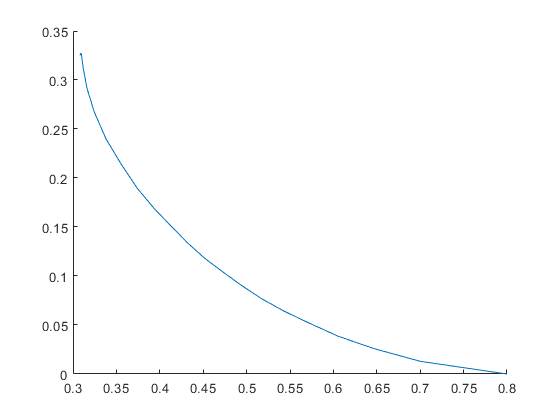

plot(h,phi)

f = fit(h,phi,'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       2.786  (2.407, 3.164)
       b =      -7.082  (-7.475, -6.69)

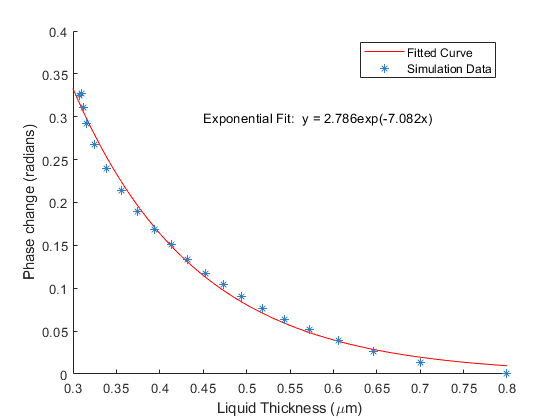

figure; hold on;
plot(f)
plot(h,phi,'color',C(2,:),'LineStyle','none','Marker',"*")
xlabel('Liquid Thickness (\mum)')
ylabel('Phase change (radians)')
legend('Fitted Curve','Simulation Data')
xlim([0.3 0.8]);
ylim([0 0.4])
text(0.45,0.3,'Exponential Fit:  y = 2.786exp(-7.082x)')

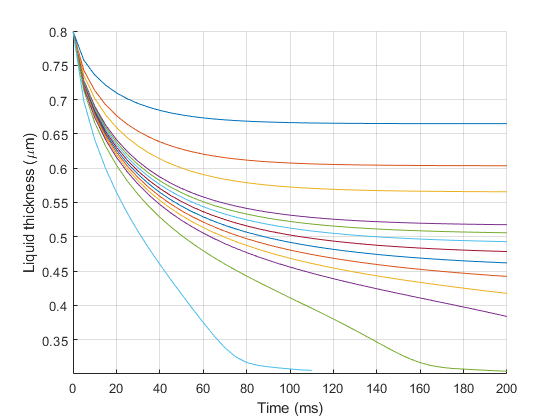

figure;hold on;
for i = 1:13
    plot(pow(2:42,1),pow(2:42,i+1))
end
xlabel('Time (ms)')
ylabel('Liquid thickness (\mum)')
grid on;

alpha = zeros(11,1);
beta = zeros(11,1);
k1 = zeros(11,1);
k2 = zeros(11,1);
k3 = zeros(11,1);
bs = 12:-1:1;
cs = 0.1*ones(12,1);
ds = 20*ones(12,1);
es = 0.2*ones(12,1);
as = 0.8-cs-es;

Eqn = 'a*exp(-b*x)+c*exp(-d*x)+e'

Eqn = 'a*exp(-b*x)+c*exp(-d*x)+e'

%Eqn = 'a*exp(-b*x)+c'

figure; hold on;
for i = 1:11
    f1 = fit(pow(2:42,1)/200,pow(2:42,i+1),Eqn,'Start', [as(i) bs(i) cs(i) ds(i) es(i)],'Robust','Bisquare');
    plot(f1,'k');
    plot(pow(2:42,1)/200,pow(2:42,i+1),'color',C(i,:),'LineStyle','none',"Marker","*")
    alpha(i) = f1.b;
    beta(i) = f1.d;
    k1(i) = f1.a;
    k2(i) = f1.c;
    k3(i) = f1.e;
end

Success. Fitting converged to a solution.


Success, but fitting stopped because change in residuals less than tolerance (TolFun).


Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.


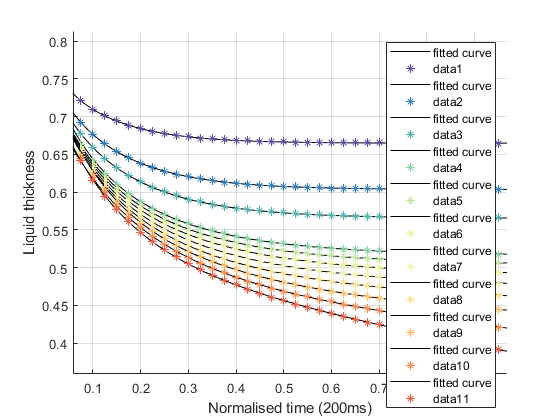

xlabel('Normalised time (200ms)')
ylabel('Liquid thickness (\mum)')
grid on;

alpha = zeros(11,1);
beta = zeros(11,1);
k1 = zeros(11,1);
k2 = zeros(11,1);
k3 = zeros(11,1);
bs = 12:-1:1;
cs = 0.1:0.05:0.7;
ds = 40:-2:16-11*2;
as = 0.2:0.05:0.8;

Eqn = 'a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8'

Eqn = 'a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8'

%Eqn = 'a*exp(-b*x)+c'

figure; hold on;
for i = 1:11
    f1 = fit(pow(2:42,1)/200,pow(2:42,i+1),Eqn,'Start', [as(i) bs(i) cs(i) ds(i)],'Robust','Bisquare')
    plot(f1,'k');
    plot(pow(2:42,1)/200,pow(2:42,i+1),'color',C(i,:),'LineStyle','none',"Marker","*")
    alpha(i) = f1.b;
    beta(i) = f1.d;
    k1(i) = f1.a;
    k2(i) = f1.c;

end

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1019  (0.1014, 0.1024)
       b =        8.29  (8.258, 8.323)
       c =     0.03325  (0.03274, 0.03376)
       d =       40.42  (39.67, 41.18)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1468  (0.1455, 0.1481)
       b =       7.184  (7.132, 7.236)
       c =      0.0497  (0.04834, 0.05105)
       d =       33.03  (32.02, 34.05)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1736  (0.172, 0.1752)
       b =        6.41  (6.356, 6.463)
       c =     0.06096  (0.05927, 0.06264)
       d =       32.58  (31.47, 33.69)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1818  (0.1763, 0.1873)
       b =        4.97  (4.862, 5.078)
       c =      0.1018  (0.09611, 0.1075)
       d =       16.64  (15.96, 17.33)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1831  (0.1762, 0.19)
       b =       4.617  (4.486, 4.747)
       c =      0.1128  (0.1056, 0.12)
       d =       15.58  (14.86, 16.31)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1834  (0.1754, 0.1915)
       b =        4.21  (4.062, 4.359)
       c =      0.1262  (0.1177, 0.1348)
       d =       14.49  (13.78, 15.19)

Success. Fitting converged to a solution.


f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1787  (0.1685, 0.1889)
       b =       3.686  (3.501, 3.871)
       c =      0.1472  (0.1361, 0.1582)
       d =       12.74  (12.08, 13.4)

Success, but fitting stopped because change in residuals less than tolerance (TolFun).


f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =       0.181  (0.1702, 0.1918)
       b =       3.165  (2.959, 3.371)
       c =      0.1645  (0.1523, 0.1767)
       d =       12.07  (11.42, 12.72)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.1845  (0.1739, 0.195)
       b =       2.509  (2.275, 2.743)
       c =       0.188  (0.1745, 0.2015)
       d =        11.1  (10.49, 11.71)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.2046  (0.198, 0.2112)
       b =       1.753  (1.487, 2.02)
       c =      0.2126  (0.1981, 0.2271)
       d =        10.4  (9.792, 11.01)

f1 =      General model:
     f1(x) = a*(exp(-b*x)-1)+c*(exp(-d*x)-1) + 0.8
     Coefficients (with 95% confidence bounds):
       a =      0.3121  (0.2585, 0.3656)
       b =      0.8098  (0.5003, 1.119)
       c =      0.2413  (0.2259, 0.2567)
       d =       9.689  (9.078, 10.3)

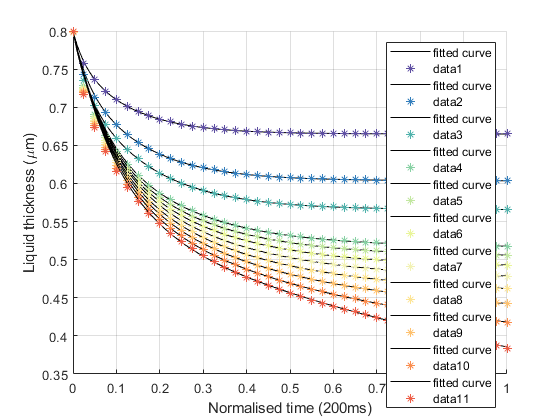

xlabel('Normalised time (200ms)')
ylabel('Liquid thickness (\mum)')
grid on;

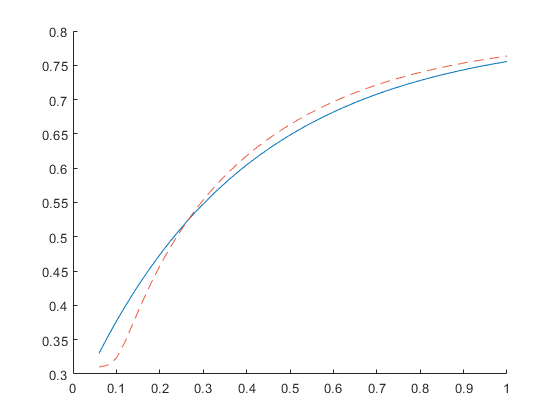

figure; hold on;

b = 3;
c = -0.2;
d = 2;
e = 0.8;
a = -0.35;


xt = xr/50;
yt = a*exp(-b*xt)+c*exp(-d*xt)+e;
plot(xt,yt)
plot(xr/50,yr,'color',C(i,:),'LineStyle','--')

pow_vec = pow(1,2:12);
figure; hold on;
plot(pow_vec,alpha+beta);
figure; hold on;
plot(pow_vec,alpha.*beta)

figure; hold on;
plot(pow_vec,alpha.*beta.*k3)

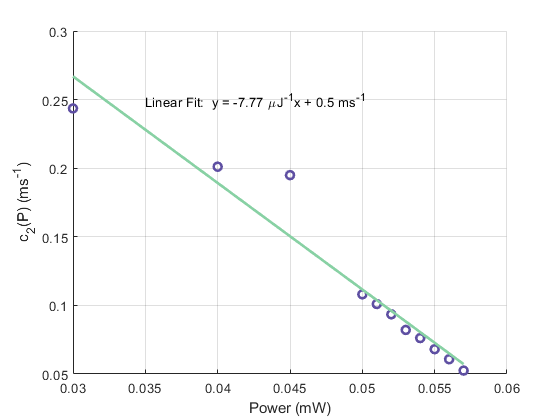

[p1,~] = polyfit(pow_vec,alpha+beta,1);
y1 = polyval(p1,pow_vec);
figure; hold on;
plot(pow_vec,(alpha+beta)/200,'linewidth',2,"Color",C(1,:),"LineStyle",'none',"Marker","o");
plot(pow_vec,y1/200,'linewidth',2,"Color",C(4,:));
xlabel('Power (mW)')
ylabel('c_2(P) (ms^{-1})')
text(0.035,0.25,'Linear Fit:  y = -7.77 \muJ^{-1}x + 0.5 ms^{-1}')
grid on;

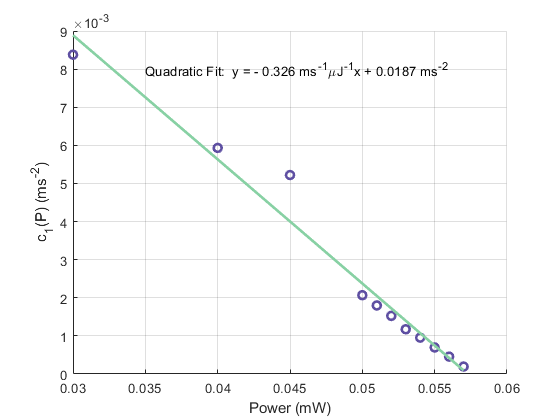

[p2,~] = polyfit(pow_vec,alpha.*beta,1);
y2 = polyval(p2,pow_vec);
figure; hold on;
plot(pow_vec,alpha.*beta/40000,'linewidth',2,"Color",C(1,:),"LineStyle",'none',"Marker","o");
plot(pow_vec,y2/40000,'linewidth',2,"Color",C(4,:));
xlabel('Power (mW)')
ylabel('c_1(P) (ms^{-2})')
text(0.035,0.008,'Quadratic Fit:  y = - 0.326 ms^{-1}\muJ^{-1}x + 0.0187 ms^{-2}')
grid on;

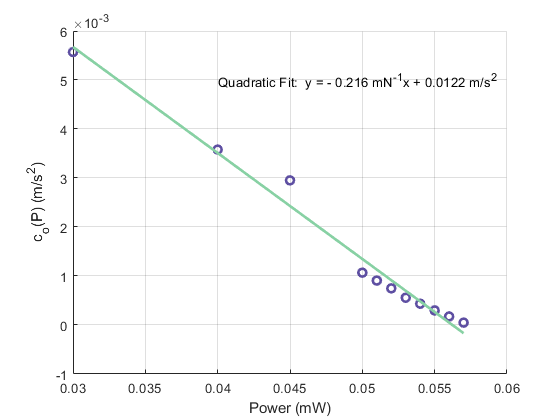

[p3,S] = polyfit(pow_vec,(0.8-k1-k2).*alpha.*beta,1);
y3 = polyval(p3,pow_vec);
figure; hold on;
plot(pow_vec,(0.8-k1-k2).*alpha.*beta/40000,'linewidth',2,"Color",C(1,:),"LineStyle",'none',"Marker","o");
plot(pow_vec,y3/40000,'linewidth',2,"Color",C(4,:))
xlabel('Power (mW)')
ylabel('c_o(P) (m/s^{2})')
text(0.04,0.005,'Quadratic Fit:  y = - 0.216 mN^{-1}x + 0.0122 m/s^{2}')
grid on;

b = 12;
c = -0.1;
d = 10;
e = 0.8;
a = -0.1;
Eqn = 'a*exp(-b*x)+c*exp(-d*x)+0.8'

Eqn = 'a*exp(-b*x)+c*exp(-d*x)+0.8'

figure; hold on;
xr = restore(:,1);
yr = restore(:,2);
fr = fit(xr/50,yr,Eqn,'Start',[a b c d],'Robust','Bisquare');

Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.


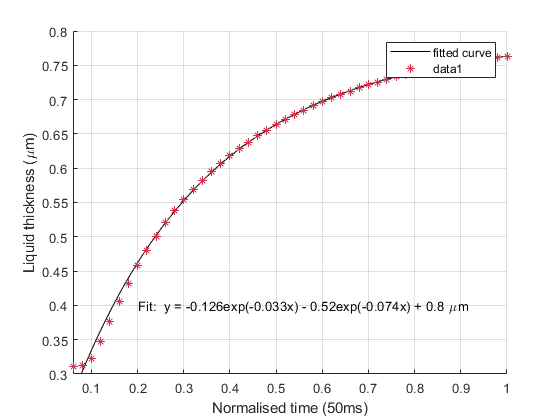

plot(fr,'k');
plot(xr/50,yr,'color',C(12,:),'LineStyle','none',"Marker","*")
xlabel('Normalised time (50ms)')
ylabel('Liquid thickness (\mum)')
text(0.2,0.4,'Fit:  y = -0.126exp(-0.033x) - 0.52exp(-0.074x) + 0.8 \mum')
grid on;
xlim([0.06 1])
ylim([0.3 0.8])

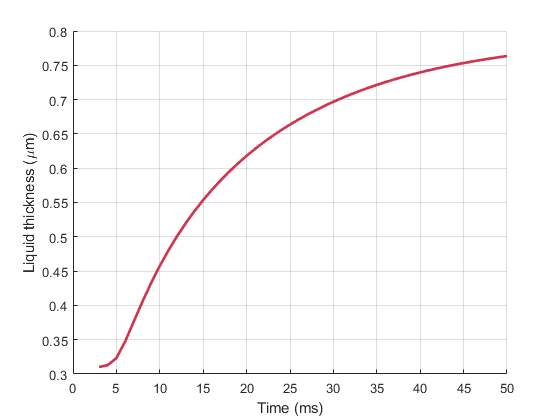

figure; hold on;
xr = restore(:,1);
yr = restore(:,2);
plot(xr,yr,'color',C(12,:),'Linewidth',2)
xlabel('Time (ms)')
ylabel('Liquid thickness (\mum)')
grid on;
%xlim([0.06 1])
ylim([0.3 0.8])